# MECH 6326 - HW 3

Author: Jonas Wagner

Date: 2023-04-03

clear
close all

## Problem 1

clear
% Matrix Setup
P_1 = eye(4);
P_1(1,:) = [0.6, 0.4, 0, 0];
P_1(2,:) = [0.2, 0.6, 0.1, 0]

P_1 =     0.6000    0.4000         0         0
    0.2000    0.6000    0.1000         0
         0         0    1.0000         0
         0         0         0    1.0000


P_2 = eye(4);
P_2(2,:) = [0.2, 0.6, 0.1, 0]

P_2 =     1.0000         0         0         0
    0.2000    0.6000    0.1000         0
         0         0    1.0000         0
         0         0         0    1.0000


## Part 1

rng(1)
% State Space
n = 10;
X_0 = zeros(n,n,4);
X_0(:,:,1) = 1;
I_0 = [
    2,2;
    9,9
];
P_0 = [];
for i = 1:size(I_0,1)
    X_0(I_0(i,1),(I_0(i,2)),1) = 0;
    X_0(I_0(i,1),(I_0(i,2)),2) = 1;
end
for i = 1:size(P_0,1)
    X_0(P_0(i,1),P_0(i,2),1) = 0;
    X_0(P_0(i,1),P_0(i,2),2) = 1;
end

% Run Simulation
nSims = 50;
N = 50;

for i = 1:nSims
    X{i} = X_0;
    for k = 1:N
        X{i} = MECH6326_HW3_pblm1_evolution(X{i},P_1,P_2);
    end
    dead(i) = sum(sum(X{i}(:,:,3)));
end
avgDead = mean(dead)

avgDead = 77.3600

maxDead = max(dead)

maxDead = 88

## Part2

rng(1)
% State Space
n = 10;
X_0 = zeros(n,n,4);
X_0(:,:,1) = 1;
I_0 = [
    2,2;
    9,9
];
P_0 = [
    2,3;
    3,2;
    3,7;
    4,6;
    6,4;
    7,3;
    8,9;
    9,8
];
for i = 1:size(I_0,1)
    X_0(I_0(i,1),(I_0(i,2)),1) = 0;
    X_0(I_0(i,1),(I_0(i,2)),2) = 1;
end
for i = 1:size(P_0,1)
    X_0(P_0(i,1),P_0(i,2),1) = 0;
    X_0(P_0(i,1),P_0(i,2),4) = 1;
end

% Run Simulation
nSims = 50;
N = 50;

for i = 1:nSims
    X{i} = X_0;
    for k = 1:N
        X{i} = MECH6326_HW3_pblm1_evolution(X{i},P_1,P_2);
    end
    dead(i) = sum(sum(X{i}(:,:,3)));
end
avgDead = mean(dead)

avgDead = 69.0200

maxDead = max(dead)

maxDead = 76

## Problem 2

clear
P = [
0.2	0.1	0	0	0	0	0	0	0	0	0	0	0	0	0	0
0.3	0.1	0.7	0	0	0	0	0	0	0	0	0	0	0	0	0
0	0.6	0.2	0	0	0	0	0	0	0	0	0	0	0	0	0
0	0	0	0	0.8	0	0	0	0	0	0	0	0	0	0	0
0	0	0	0.5	0.1	0	0	0	0	0	0	0	0	0	0	0
0	0	0	0	0	0.2	0.2	0	0	0	0	0	0	0	0	0
0	0.2	0	0	0	0.4	0.4	0.9	0.2	0	0	0	0	0	0	0
0	0	0	0	0	0	0.3	0.1	0	1	0	0	0	0	0	0
0	0	0	0	0	0.4	0	0	0.2	0	0	0	0	0	0	0
0	0	0	0	0	0	0.1	0	0.6	0	0	0	0	0	0	0
0	0	0	0	0.1	0	0	0	0	0	0.2	0.5	0.1	0	0	0
0	0	0	0	0	0	0	0	0	0	0.1	0.2	0	0	0	0
0	0	0	0	0	0	0	0	0	0	0.7	0.3	0.9	0	0	0
0.5	0	0	0	0	0	0	0	0	0	0	0	0	1	0	0
0	0	0.1	0	0	0	0	0	0	0	0	0	0	0	1	0
0	0	0	0.5	0	0	0	0	0	0	0	0	0	0	0	1
]';

eigP = eig(P)

eigP =   -0.5227 + 0.0000i
   0.2000 + 0.0000i
   0.8227 + 0.0000i
  -0.5844 + 0.0000i
   0.6844 + 0.0000i
   1.0000 + 0.0000i
  -0.3433 + 0.3159i
  -0.3433 - 0.3159i
   0.2933 + 0.3592i
   0.2933 - 0.3592i


L = round(P^500,7)

L =          0         0         0         0         0    0.0267    0.1070    0.0564    0.0134    0.0187         0         0         0    0.6944    0.0833         0
         0         0         0         0         0    0.0713    0.2852    0.1505    0.0357    0.0499         0         0         0    0.1852    0.2222         0
         0         0         0         0         0    0.0624    0.2496    0.1317    0.0312    0.0437         0         0         0    0.1620    0.3194         0
         0         0         0         0         0         0         0         0         0         0    0.0118    0.0015    0.0868         0         0    0.9000
         0         0         0         0         0         0         0         0         0         0    0.0235    0.0029    0.1735         0         0    0.8000
         0         0         0         0         0    0.1203    0.4813    0.2540    0.0602    0.0842         0         0         0         0         0         0
         0         0         0

% Part 3
n = size(P,1);
d_0(n,1) = 0; d_0(1,1) = 1;
d_infty = (d_0'*P)'

d_infty =     0.2000
    0.3000
         0
         0
         0
         0
         0
         0
         0
         0


d_0 = zeros(n,1);
d_0(4,1) = 1;
d_infty = (d_0'*P)'

d_infty =          0
         0
         0
         0
    0.5000
         0
         0
         0
         0
         0


d_0 = zeros(n,1);
d_0(2,1) = 0.5; d_0(5,1) = 0.5;
d_infty = (d_0'*P)'

d_infty =     0.0500
    0.0500
    0.3000
    0.4000
    0.0500
         0
    0.1000
         0
         0
         0


## Problem 3

clear
n = 7;
P_w = (1/3)*eye(7);
P_l = [P_w(2:end,:); P_w(1,:)];
P_r = [P_w(end,:); P_w(1:end-1,:)];
P_lr = (P_l + P_r);
P = [P_lr, P_w; zeros(n), eye(n)]

P =          0    0.3333         0         0         0         0    0.3333    0.3333         0         0         0         0         0         0
    0.3333         0    0.3333         0         0         0         0         0    0.3333         0         0         0         0         0
         0    0.3333         0    0.3333         0         0         0         0         0    0.3333         0         0         0         0
         0         0    0.3333         0    0.3333         0         0         0         0         0    0.3333         0         0         0
         0         0         0    0.3333         0    0.3333         0         0         0         0         0    0.3333         0         0
         0         0         0         0    0.3333         0    0.3333         0         0         0         0         0    0.3333         0
    0.3333         0         0         0         0    0.3333         0         0         0         0         0         0         0    0.3333
         


L = P^100

L =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.4483    0.1724    0.0690    0.0345    0.0345    0.0690    0.1724
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.1724    0.4483    0.1724    0.0690    0.0345    0.0345    0.0690
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0690    0.1724    0.4483    0.1724    0.0690    0.0345    0.0345
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0345    0.0690    0.1724    0.4483    0.1724    0.0690    0.0345
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0345    0.0345    0.0690    0.1724    0.4483    0.1724    0.0690
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0690    0.0345    0.0345    0.0690    0.1724    0.4483    0.1724
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.1724    0.0690    0.0345    0.0345    0.0690    0.1724    0.4483
         


d_0(1)=1; d_0(2*n,1) = 0;
d_infty = round((d_0' * L)',7)

d_infty =          0
         0
         0
         0
         0
         0
         0
    0.4483
    0.1724
    0.0690


p_win = d_infty(n+1)

p_win = 0.4483

## Problem 4

clear

P = [
    0   0   0.4 0.6
    0.3 0   0.3 0.4
    0   0.5 0   0.5
    0   0.7 0.3 0
]

P =          0         0    0.4000    0.6000
    0.3000         0    0.3000    0.4000
         0    0.5000         0    0.5000
         0    0.7000    0.3000         0


% Part a
n = size(P,2);
E = [4];

P_a = P;
P_a(E,:) = 0;
P_a(E,n+1) = 1;
P_a(n+1,n+1) = 1

P_a =          0         0    0.4000    0.6000         0
    0.3000         0    0.3000    0.4000         0
         0    0.5000         0    0.5000         0
         0         0         0         0    1.0000
         0         0         0         0    1.0000


d_0(n+1,1) = 0;
d_0(1,1) = 1;

tau = 10;
P_tau = P_a^tau;
d_tau = d_0'*P_tau;
p_tau = sum(d_tau(E))

p_tau = 0.0010

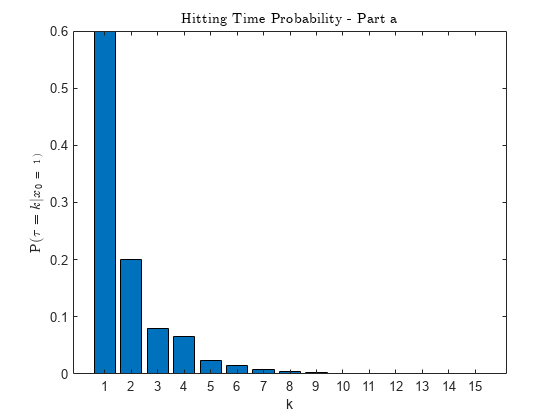


for tau = 1:15
    P_tau = P_a^tau;
    d_tau = d_0'*P_tau;
    p_tau(tau) = sum(d_tau(E));
end
bar(p_tau)
title("Hitting Time Probability - Part a", 'Interpreter','latex')
xlabel("k")
ylabel("P($\tau = k | x_0 = 1$)",'Interpreter','latex')
saveas(gcf,"figs/pblm4a.png")


% Part b
E_s = [2];
E_t = [4];
P_11 = P; P_11(E_s,:) = 0;
P_12 = zeros(n); P_12(E_s,:) = P(E_s,:);
P_21 = P; P_21(E_t,:) = 0;
P_b = [P_11, P_12; P_21, zeros(n)];
P_b(n+E_s,2*n+1) = 1;
P_b(2*n+1,2*n+1) = 1

P_b =          0         0    0.4000    0.6000         0         0         0         0         0
         0         0         0         0    0.3000         0    0.3000    0.4000         0
         0    0.5000         0    0.5000         0         0         0         0         0
         0    0.7000    0.3000         0         0         0         0         0         0
         0         0    0.4000    0.6000         0         0         0         0         0
    0.3000         0    0.3000    0.4000         0         0         0         0    1.0000
         0    0.5000         0    0.5000         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0    1.0000



d_0 = zeros(2*n+1,1);
d_0(1) = 1 

d_0 =      1
     0
     0
     0
     0
     0
     0
     0
     0


tau = 10;
P_tau = P_b^tau;
d_tau = d_0'*P_tau;
p_tau = sum(d_tau(E))

p_tau = 0.0662

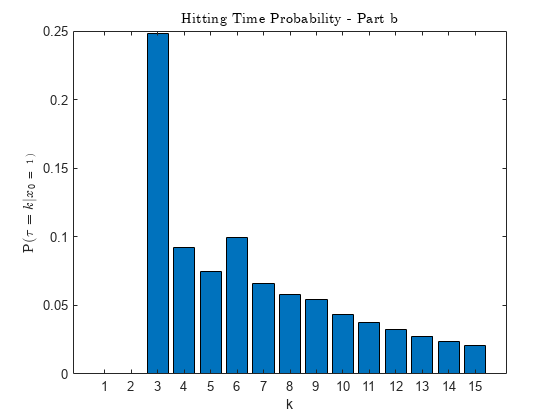

for tau = 1:15
    P_tau = P_b^tau;
    d_tau = d_0'*P_tau;
    p_tau(tau) = sum(d_tau(n+E));
end
bar(p_tau)
title("Hitting Time Probability - Part b", 'Interpreter','latex')
xlabel("k")
ylabel("P($\tau = k | x_0 = 1$)",'Interpreter','latex')
saveas(gcf,"figs/pblm4b.png")